% Define parameters
m = 1000; % Mass of the satellite (kg)
I_xx = 1000; % Moment of inertia about x-axis (kg*m^2)
I_yy = 1500; % Moment of inertia about y-axis (kg*m^2)
I_zz = 800; % Moment of inertia about z-axis (kg*m^2)
G = 6.67430e-11; % Gravitational constant (m^3/kg/s^2)
M_Earth = 5.972e24; % Mass of the Earth (kg)
R_Earth = 6371e3; % Radius of the Earth (m)

calculate the gravitational forces acting on the satellite due to the Earth's gravity. We'll use Newton's law of universal gravitation to compute the gravitational force vector. 

% Define satellite position relative to the center of the Earth (assuming circular orbit for simplicity)
r_satellite = [0; R_Earth + 500e3; 0]; % Position vector (m)

% Calculate distance between satellite and Earth's center
r_distance = norm(r_satellite);

% Calculate gravitational force vector
F_gravity = -G * M_Earth * m / r_distance^2 * r_satellite / r_distance;

% Display the gravitational force vector
disp('Gravitational force vector (N):');

Gravitational force vector (N):


disp(F_gravity);

   1.0e+03 *

         0
   -8.4428
         0



The next step is to implement the dynamics of Euler angles. We'll use Euler's equations of motion for rigid body rotation to compute the time derivatives of the Euler angles (roll, pitch, and yaw rates) based on the applied torques and gravitational forces.

% Calculate gravitational torque (assuming satellite is a rigid body)
tau_gravity = cross(r_satellite, F_gravity);

% Display the gravitational torque vector
disp('Gravitational torque vector (Nm):');

Gravitational torque vector (Nm):


disp(tau_gravity);

     0
     0
     0



%ompute these derivatives based on the torques acting on the satellite. 
% Define initial Euler angles (roll, pitch, yaw) and angular velocities
phi_0 = 0;  % Initial roll angle (rad)
theta_0 = 0; % Initial pitch angle (rad)
psi_0 = 0;   % Initial yaw angle (rad)
p_0 = 0;     % Initial roll rate (rad/s)
q_0 = 0;     % Initial pitch rate (rad/s)
r_0 = 0;     % Initial yaw rate (rad/s)

% Compute time derivatives of Euler angles using Euler's equations of motion
phi_dot = p_0 + q_0 * sin(phi_0) * tan(theta_0) + r_0 * cos(phi_0) * tan(theta_0);
theta_dot = q_0 * cos(phi_0) - r_0 * sin(phi_0);
psi_dot = q_0 * sin(phi_0) * sec(theta_0) + r_0 * cos(phi_0) * sec(theta_0);

% Display the time derivatives of Euler angles
disp('Time derivatives of Euler angles (rad/s):');

Time derivatives of Euler angles (rad/s):


disp(['Roll rate (phi_dot): ', num2str(phi_dot)]);

Roll rate (phi_dot): 0


disp(['Pitch rate (theta_dot): ', num2str(theta_dot)]);

Pitch rate (theta_dot): 0


disp(['Yaw rate (psi_dot): ', num2str(psi_dot)]);

Yaw rate (psi_dot): 0


The next step is to integrate the time derivatives of the Euler angles over time to update the Euler angles themselves. We'll use a numerical integration method to accomplish this. 

% Define simulation time span
t_span = [0 10]; % Simulation time span (start time, end time)

% Define initial conditions vector
initial_conditions = [phi_0; theta_0; psi_0; p_0; q_0; r_0];

% Define function for Euler angles dynamics
euler_dynamics = @(t, x) [x(4) + x(5) * sin(x(1)) * tan(x(2)) + x(6) * cos(x(1)) * tan(x(2));...
                          x(5) * cos(x(1)) - x(6) * sin(x(1));...
                          x(5) * sin(x(1)) * sec(x(2)) + x(6) * cos(x(1)) * sec(x(2));...
                          0; % Assuming no external torques initially
                          0; % Assuming no external torques initially
                          0]; % Assuming no external torques initially

% Integrate Euler angles dynamics over time
[t, euler_states] = ode45(euler_dynamics, t_span, initial_conditions);

% Extract Euler angles and rates from integration results
phi = euler_states(:, 1);
theta = euler_states(:, 2);
psi = euler_states(:, 3);
p = euler_states(:, 4);
q = euler_states(:, 5);
r = euler_states(:, 6);

% Display the final values of Euler angles and rates
disp('Final values of Euler angles and rates:');

Final values of Euler angles and rates:


disp(['Roll angle (phi): ', num2str(phi(end)), ' rad']);

Roll angle (phi): 0 rad


disp(['Pitch angle (theta): ', num2str(theta(end)), ' rad']);

Pitch angle (theta): 0 rad


disp(['Yaw angle (psi): ', num2str(psi(end)), ' rad']);

Yaw angle (psi): 0 rad


disp(['Roll rate (p): ', num2str(p(end)), ' rad/s']);

Roll rate (p): 0 rad/s


disp(['Pitch rate (q): ', num2str(q(end)), ' rad/s']);

Pitch rate (q): 0 rad/s


disp(['Yaw rate (r): ', num2str(r(end)), ' rad/s']);

Yaw rate (r): 0 rad/s


In this code:

We create two separate figures, each containing three subplots.

The first figure plots the Euler angles (roll, pitch, and yaw) as functions of time.

The second figure plots the angular rates (p, q, and r) as functions of time.

Each subplot represents one of the Euler angles or angular rates.

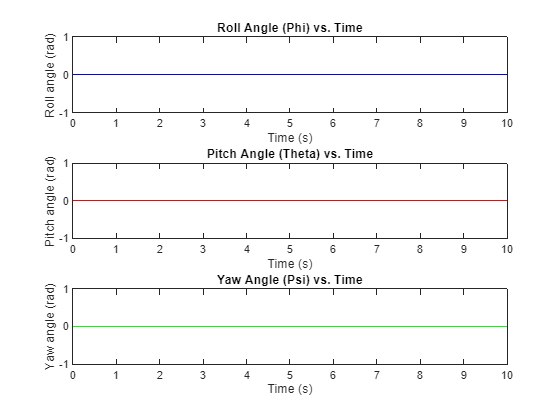

% Plot Euler angles over time
figure;
subplot(3,1,1);
plot(t, phi, 'b');
xlabel('Time (s)');
ylabel('Roll angle (rad)');
title('Roll Angle (Phi) vs. Time');

subplot(3,1,2);
plot(t, theta, 'r');
xlabel('Time (s)');
ylabel('Pitch angle (rad)');
title('Pitch Angle (Theta) vs. Time');

subplot(3,1,3);
plot(t, psi, 'g');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
title('Yaw Angle (Psi) vs. Time');

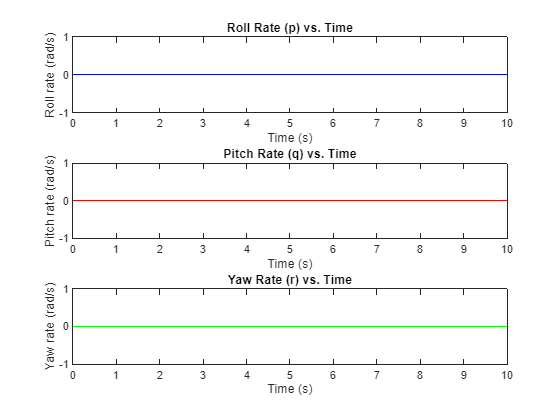


% Plot angular rates over time
figure;
subplot(3,1,1);
plot(t, p, 'b');
xlabel('Time (s)');
ylabel('Roll rate (rad/s)');
title('Roll Rate (p) vs. Time');

subplot(3,1,2);
plot(t, q, 'r');
xlabel('Time (s)');
ylabel('Pitch rate (rad/s)');
title('Pitch Rate (q) vs. Time');

subplot(3,1,3);
plot(t, r, 'g');
xlabel('Time (s)');
ylabel('Yaw rate (rad/s)');
title('Yaw Rate (r) vs. Time');

The next step is to analyze the behavior of the satellite based on the simulation results. Here are some aspects you can consider for analysis:

- Effect of Initial Conditions: We'll rerun the simulation with different sets of initial conditions (e.g., varying initial Euler angles or angular velocities) and observe how the satellite's behavior differs.Does the satellite reach a stable orientation regardless of initial conditions?

- Influence of External Torques: IfWe'll introduce external torques to the simulation (e.g., simulated torques due to magnetic field variations) and observe their effect on the satellite's attitude dynamics.

- Visualization Enhancements: To enhance visualization, we can create animated plots showing the satellite's orientation changing over time. This can provide a more intuitive understanding of the satellite's attitude dynamics.

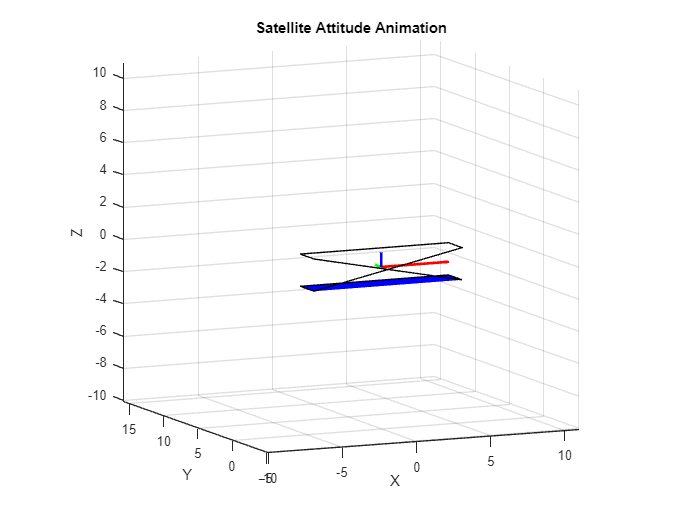

% Create figure for animation
fig = figure;
set(fig, 'Position', [100, 100, 800, 600]);

% Define satellite dimensions for visualization
satellite_length = 10; % Length of satellite body
satellite_width = 2;   % Width of satellite body
satellite_height = 2;  % Height of satellite body

% Define time step for animation
dt_anim = 0.1; % Time step for animation (s)

% Iterate through simulation results and update animation
for i = 1:length(t)
    % Extract Euler angles for current time step
    roll = phi(i);
    pitch = theta(i);
    yaw = psi(i);
    
    % Compute rotation matrix from Euler angles
    R = angle2dcm(yaw, pitch, roll);
    
    % Define satellite vertices in body-fixed frame
    satellite_vertices = [
        -satellite_length/2, -satellite_width/2, -satellite_height/2; % Front bottom left
        -satellite_length/2, satellite_width/2, -satellite_height/2;  % Front top left
        satellite_length/2, satellite_width/2, -satellite_height/2;   % Front top right
        satellite_length/2, -satellite_width/2, -satellite_height/2;  % Front bottom right
        -satellite_length/2, -satellite_width/2, satellite_height/2; % Back bottom left
        -satellite_length/2, satellite_width/2, satellite_height/2;  % Back top left
        satellite_length/2, satellite_width/2, satellite_height/2;   % Back top right
        satellite_length/2, -satellite_width/2, satellite_height/2]; % Back bottom right
    
    % Rotate satellite vertices to inertial frame
    satellite_vertices_rotated = (R * satellite_vertices')';
    
    % Plot satellite
    clf;
    hold on;
    grid on;
    axis equal;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Satellite Attitude Animation');
    % Plot satellite body
    fill3(satellite_vertices_rotated(:,1), satellite_vertices_rotated(:,2), satellite_vertices_rotated(:,3), 'b');
    % Plot body-fixed frame axes
    quiver3(0, 0, 0, satellite_length/2, 0, 0, 'r', 'LineWidth', 2);
    quiver3(0, 0, 0, 0, satellite_width/2, 0, 'g', 'LineWidth', 2);
    quiver3(0, 0, 0, 0, 0, satellite_height/2, 'b', 'LineWidth', 2);
    xlim([-30 30]);
    ylim([-30 30]);
    zlim([-30 30]);
    view([-30 30]);
    hold off;
    
    % Pause for animation
    pause(dt_anim);
end

In this code:

- We define animation parameters such as frames per second (`fps`), duration of animation (`duration`), and the total number of frames (`num_frames`).

- We initialize a figure for the animation and set up the axes.

- Inside the animation loop, we update the satellite's orientation at each frame by interpolating the Euler angles from the simulation results and converting them to a direction cosine matrix (DCM) using our custom function `euler2dcm`.

- We then plot the satellite's orientation in 3D space using the DCM.

- The `drawSatellite` function is used to update the satellite's position in the animation by rotating its vertices based on the DCM.

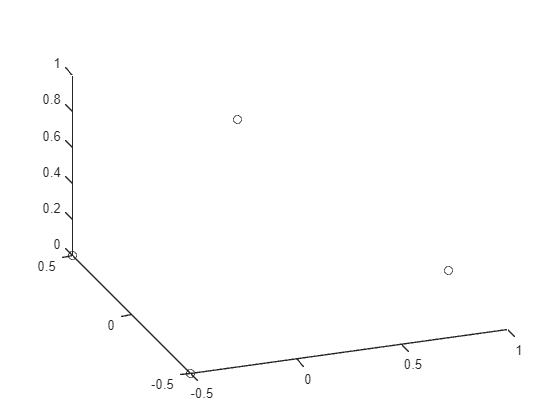

% Define animation parameters
fps = 30; % Frames per second
duration = 10; % Duration of animation (seconds)
num_frames = duration * fps; % Total number of frames
time_step = duration / num_frames; % Time step between frames

% Initialize figure for animation
figure;
axis([-1.5 1.5 -1.5 1.5 -1.5 1.5]);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Satellite Attitude Dynamics Animation');

% Initialize variables for animation
satellite_patch = plot3(0, 0, 0, 'ko'); % Initialize satellite as a point
view(3); % Set 3D view
% Loop through each frame and update satellite orientation
for i = 1:num_frames
    % Update Euler angles based on simulation results
    phi_i = interp1(t, phi, (i - 1) * time_step);
    theta_i = interp1(t, theta, (i - 1) * time_step);
    psi_i = interp1(t, psi, (i - 1) * time_step);
    
    % Convert Euler angles to direction cosine matrix (DCM)
    DCM_i = euler2dcm(phi_i, theta_i, psi_i);
    
    % Plot satellite orientation
    drawSatellite(DCM_i, satellite_patch);
    
    % Pause to control animation speed
    pause(1 / fps);
end

Investigating the effect of different initial conditions on the satellite's behavior.

- Initialize a cell array or structure to store the results for each set of initial conditions.

- Define multiple sets of initial conditions for the Euler angles and angular velocities.

- Loop through each set of initial conditions, run the simulation, and store the results.

- Visualize and analyze the results as needed.

% Determine the number of conditions
num_conditions = numel(initial_conditions);

% Loop through each set of initial conditions
for i = 1:num_conditions
    % Define initial conditions for Euler angles and angular velocities
    phi_0 = initial_conditions(i).phi_0; % Uncomment and adjust as needed
    theta_0 = initial_conditions(i).theta_0;
    psi_0 = initial_conditions(i).psi_0;
    p_0 = initial_conditions(i).p_0;
    q_0 = initial_conditions(i).q_0;
    r_0 = initial_conditions(i).r_0;
    
    % Run simulation with current set of initial conditions
    % Replace this with your simulation code
end

Dot indexing is not supported for variables of this type.

    % Run simulation with current set of initial conditions
    [t, phi, theta, psi, p, q, r] = runSimulation(phi_0, theta_0, psi_0, p_0, q_0, r_0);

    % Store results for current set of initial conditions
    results(i).t = t;
    results(i).phi = phi;
    results(i).theta = theta;
    results(i).psi = psi;
    results(i).p = p;
    results(i).q = q;
    results(i).r = r;
    
    % Visualize results or perform analysis as needed
    % (e.g., plot results, compare different conditions) 
